使用MATLAB提供的DataSet做訓練

clear;
clc;

讀取DataSet

unzip vehicleDatasetImages.zip %解壓縮vehicleDatasetImages檔
data = load("vehicleDatasetGroundTruth.mat");
DataSet = data.vehicleDataset;

顯示目前資訊

DataSet(1:4,:)

ans = 4×2 table
              imageFilename                   vehicle     
    _________________________________    _________________

    {'vehicleImages/image_00001.jpg'}    {[220 136 35 28]}
    {'vehicleImages/image_00002.jpg'}    {[175 126 61 45]}
    {'vehicleImages/image_00003.jpg'}    {[108 120 45 33]}
    {'vehicleImages/image_00004.jpg'}    {[124 112 38 36]}


將DataSet分成訓練集、驗證集與測試集

rng("default");
shuffledIndices = randperm(height(DataSet));
idx = floor(0.6 * length(shuffledIndices) );

trainingIdx = 1:idx;
trainingDataTbl = DataSet(shuffledIndices(trainingIdx),:);

validationIdx = idx+1 : idx + 1 + floor(0.1 * length(shuffledIndices) );
validationDataTbl = DataSet(shuffledIndices(validationIdx),:);

testIdx = validationIdx(end)+1 : length(shuffledIndices);
testDataTbl = DataSet(shuffledIndices(testIdx),:);

做DataSet資料的前處理

imdsTrain = imageDatastore(trainingDataTbl{:,"imageFilename"});
bldsTrain = boxLabelDatastore(trainingDataTbl(:,2:end));

imdsValidation = imageDatastore(validationDataTbl{:,"imageFilename"});
bldsValidation = boxLabelDatastore(validationDataTbl(:,2:end));

imdsTest = imageDatastore(testDataTbl{:,"imageFilename"});
bldsTest = boxLabelDatastore(testDataTbl(:,2:end));

trainingData = combine(imdsTrain,bldsTrain);
validationData = combine(imdsValidation,bldsValidation);
testData = combine(imdsTest,bldsTest);

使用Matlab的內建程式檢測資訊是否正確，使用validateInputData.m檔案

validateInputData(trainingData);
validateInputData(validationData);
validateInputData(testData);

顯示其中一張影像，並把物件框資訊也顯示出來

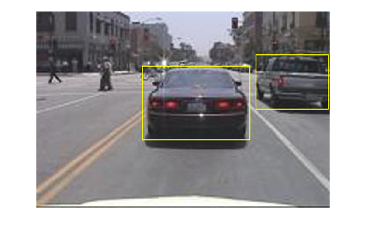

data = read(trainingData);
I = data{1};
bbox = data{2};
annotatedImage = insertShape(I,"Rectangle",bbox);
annotatedImage = imresize(annotatedImage,2);
figure
imshow(annotatedImage)

reset(trainingData);

設定訓練網路模型時的輸入影像大小

inputSize = [608 608 3];

設定DataSet的label名稱，此名稱必須跟DataSet裡面的資訊名稱一模一樣

className = "vehicle";

計算Anchor Box的尺寸，使用[estimateAnchorBoxes](docid:vision_ref#mw_cba7b62d-6557-41e6-9e4d-73ec50667c6d)函式，為YOLOv4論文提出的方法

rng("default")
trainingDataForEstimation = transform(trainingData,@(data)preprocessData(data,inputSize));

numAnchors = 9; %%%%設定Anchor Box數量
[anchors,meanIoU] = estimateAnchorBoxes(trainingDataForEstimation,numAnchors);

area = anchors(:, 1).*anchors(:,2);
[~,idx] = sort(area,"descend");

anchors = anchors(idx,:);
anchorBoxes = {anchors(1:3,:) %%%%Anchor Box數量更改，這裡也需要做更改
    anchors(4:6,:)
    anchors(7:9,:)
    };

有兩個YOLOv4架構可以選擇，1.csp-darknet53-coco , 2.tiny-yolov4-coco

detector = yolov4ObjectDetector("csp-darknet53-coco",className,anchorBoxes,InputSize=inputSize);
%detector = yolov4ObjectDetector("tiny-yolov4-coco",className,anchorBoxes,InputSize=inputSize);

做資料擴增

Color jitter augmentation in HSV space

Random horizontal flip

Random scaling by 10 percent

這裡有增加隨機旋轉1~2度訓練影像

augmentedTrainingData = transform(trainingData,@augmentData);

顯示做完資料擴增後的影像(四張)

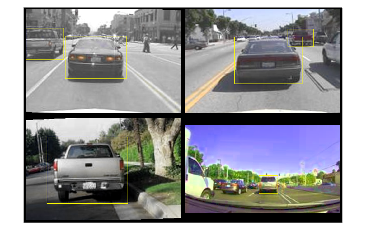

augmentedData = cell(4,1);
for k = 1:4
    data = read(augmentedTrainingData);
    augmentedData{k} = insertShape(data{1},"rectangle",data{2});
    %reset(augmentedTrainingData); %開啟後會都是同一張影像
end
figure
montage(augmentedData,BorderSize=10)

設定訓練參數

options = trainingOptions("adam",...
    GradientDecayFactor=0.9,...
    SquaredGradientDecayFactor=0.999,...
    InitialLearnRate=0.001,...
    LearnRateSchedule="none",...
    MiniBatchSize=2,...   %%batch size設定 %%%顯示卡記憶體不夠的時候，調整MiniBatchSize，越小記憶體使用量越低
    L2Regularization=0.0005,...
    MaxEpochs=10,...  %%%epoch設定
    BatchNormalizationStatistics="moving",...
    DispatchInBackground=true,...
    ResetInputNormalization=false,...
    Shuffle="every-epoch",...
    VerboseFrequency=20,...
    ValidationFrequency=100,...
    CheckpointPath=tempdir,...
    ValidationData=validationData, ...
    OutputNetwork="best-validation-loss", ...
    Plots="training-progress"); %%%顯示訓練圖表

開始訓練 或者 讀取權重檔

doTraining = false; %%%%%%%%%%%%這裡做更改!! true 或者 false
if doTraining       
    % Train the YOLO v4 detector.
    [detector,info] = trainYOLOv4ObjectDetector(augmentedTrainingData,detector,options);
    save('YOLOv4.mat','detector'); %訓練完畢後將模型儲存下來
else
    %直接讀取已經訓練好的模型
    detector = downloadPretrainedYOLOv4Detector();
    
    %%%如果使用自己訓練的權重檔，改使用下面兩行，load("改為自己的權重檔名稱")
    %pretrained = load("YOLOv4.mat");
    %detector = pretrained.detector;
end

計算準確度

%detectionResults = detect(detector,testData); %%%一般正常是使用這個去計算準確度
detectionResults = detect(detector,testData, MiniBatchSize=64);  %%%顯示卡記憶體不夠的時候，調整MiniBatchSize，預設為128，可以選擇64、32、16...等
[ap,recall,precision] = evaluateDetectionPrecision(detectionResults,testData);

畫出PR曲線圖

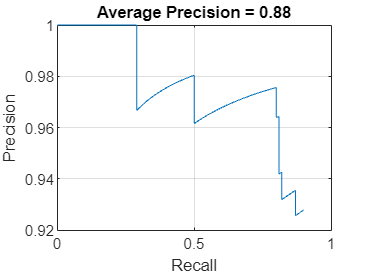

figure
plot(recall,precision)
xlabel("Recall")
ylabel("Precision")
grid on
title(sprintf("Average Precision = %.2f",ap))

從測試集隨機讀取一張影像，進行偵測

dims = size(testIdx);
number = dims(2);
random_integer = randi([1, number]);
I = imread(testDataTbl.imageFilename{random_integer});
[bboxes,scores,labels] = detect(detector,I);%偵測

顯示結果

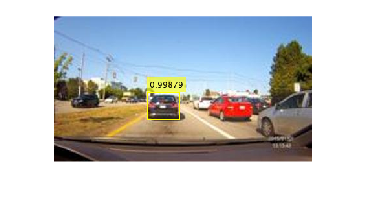

I = insertObjectAnnotation(I,"rectangle",bboxes,scores);
figure
imshow(I)

其他函式

function data = augmentData(A)
% Apply random horizontal flipping, and random X/Y scaling. Boxes that get
% scaled outside the bounds are clipped if the overlap is above 0.25. Also,
% jitter image color.

data = cell(size(A));
for ii = 1:size(A,1)
    I = A{ii,1};
    bboxes = A{ii,2};
    labels = A{ii,3};
    sz = size(I);

    if numel(sz) == 3 && sz(3) == 3
        I = jitterColorHSV(I,...
            'Contrast',0.0,...
            'Hue',0.1,...
            'Saturation',0.2,...
            'Brightness',0.2);
    end
    
    % Randomly flip and rotate image.
    degree = rand()*2 + 1; % random degree between 1 and 2
    tform = randomAffine2d('XReflection',true,'Scale',[1 1.1],'Rotation',[degree degree]);
    rout = affineOutputView(sz,tform,'BoundsStyle','centerOutput');
    I = imwarp(I,tform,'OutputView',rout);
    
    % Apply same transform to boxes.
    [bboxes,indices] = bboxwarp(bboxes,tform,rout,'OverlapThreshold',0.25);
    labels = labels(indices);
    
    % Return original data only when all boxes are removed by warping.
    if isempty(indices)
        data(ii,:) = A(ii,:);
    else
        data(ii,:) = {I,bboxes,labels};
    end
end
end

function data = preprocessData(data,targetSize)
% Resize the images and scale the pixels to between 0 and 1. Also scale the
% corresponding bounding boxes.

for ii = 1:size(data,1)
    I = data{ii,1};
    imgSize = size(I);
    
    bboxes = data{ii,2};

    I = im2single(imresize(I,targetSize(1:2)));
    scale = targetSize(1:2)./imgSize(1:2);
    bboxes = bboxresize(bboxes,scale);
    
    data(ii,1:2) = {I,bboxes};
end
end

下載預先訓練好的權重檔

function detector = downloadPretrainedYOLOv4Detector()
% Download a pretrained yolov4 detector.
if ~exist("yolov4CSPDarknet53VehicleExample_22a.mat", "file")
    if ~exist("yolov4CSPDarknet53VehicleExample_22a.zip", "file")
        disp("Downloading pretrained detector...");
        pretrainedURL = "https://ssd.mathworks.com/supportfiles/vision/data/yolov4CSPDarknet53VehicleExample_22a.zip";
        websave("yolov4CSPDarknet53VehicleExample_22a.zip", pretrainedURL);
    end
    unzip("yolov4CSPDarknet53VehicleExample_22a.zip");
end
pretrained = load("yolov4CSPDarknet53VehicleExample_22a.mat");
detector = pretrained.detector;
end